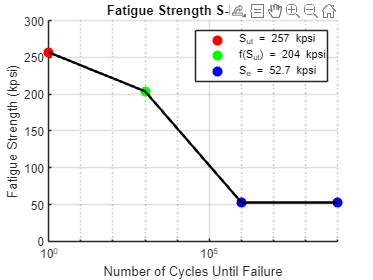

% Given data
Sut = 257; % Ultimate Tensile Strength in kpsi
fSut = 204; % Fatigue strength coefficient in kpsi
Se = 52.7; % Endurance Limit in kpsi

% Number of cycles until failure ranges
N = [1, 1e3, 1e6, 1e9]; % Specified number of cycles

% Corresponding Fatigue Strength values
S = [Sut, fSut, Se, Se]; % Stress values corresponding to the cycles

% Plotting
figure;
hold on; % Hold on to the current figure

% Plot each point individually for custom colors
plot(N(1), S(1), 'o', 'MarkerSize', 8, 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r'); % Sut point
plot(N(2), S(2), 'o', 'MarkerSize', 8, 'MarkerEdgeColor', 'g', 'MarkerFaceColor', 'g'); % fSut point
plot(N(3:end), S(3:end), 'o', 'MarkerSize', 8, 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b'); % Se points

% Plot the connecting line separately
plot(N, S, 'k-', 'LineWidth', 2); % The connecting line in black

xlabel('Number of Cycles Until Failure');
ylabel('Fatigue Strength (kpsi)');
title('Fatigue Strength S-N Curve');
axis([1, 1e9, 0, 300]); % Setting the axis limits
set(gca, 'XScale', 'log'); % Setting the x-axis to a logarithmic scale
grid on;

% Adding a legend with custom entries for each color
legend({'S_{ut} = 257 kpsi', 'f(S_{ut}) = 204 kpsi', 'S_{e} = 52.7 kpsi'}, 'Location', 'northeast');
hold off; % Release the hold on the current figure